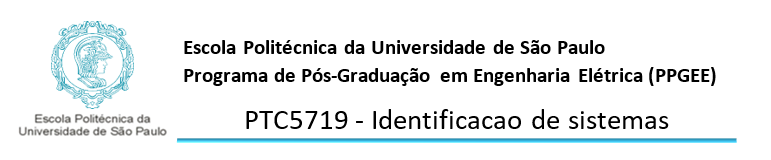

# Elton Inacio Alves Junior - 12501745

# LISTA 3

Considere o mesmo processo da 1ª lista de exercícios

**A.** Gere um sinal do tipo PRBS (sequência binária pseudo-aleatória) com 1001 pontos. Este  sinal comuta entre dois valores (neste caso -0,1 e +0,1), com um intervalo mínimo em cada  nível dado por Tb=20*T (PRBS lento). Plote o sinal gerado e verifique o seu formato. Gere  ainda outro sinal do tipo PRBS similar ao anterior, mas considerando Tb=4*T (PRBS  rápido). Plote também este sinal e comente a diferença entre os dois.

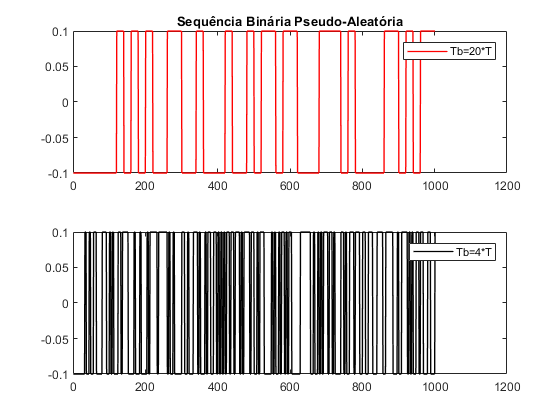

clc;clear;close all;warning off;
Tb_20T = idinput(1001,'prbs',[0 (1/20)],[-0.1 0.1]);
Tb_4T = idinput(1001,'prbs',[0 (1/4)],[-0.1 0.1]);
grid;
hold on;   

tiledlayout(2,1);
ax1 = nexttile;
plot(Tb_20T,'red','linewidth',1);
legend('Tb=20*T'); title({'Sequência Binária Pseudo-Aleatória'});
ax2 = nexttile;
plot(Tb_4T,'black','linewidth',1);    
legend('Tb=4*T'); 
linkaxes([ax1,ax2],'x');

**B. **Apresente a resposta dos processos limpo (y) e afetado por perturbações de baixa e alta  intensidade mais ruído de medição (y2), quando submetidos ao sinal PRBS lento gerado no  item anterior. Altere as sementes que gera as perturbações v1 e v2, bem como aquelas que  geram o ruído de medição em e1 e y. O motivo desta alteração é que seria impossível na  prática coletar novos dados do processo com perturbações e ruídos de medição idênticos  aos coletados ao se excitar o processo com um degrau, conforme foi feita na 2ª lista de  exercícios. Simule a planta por 1000 s.

O seguinte diagrama de blocos foi implantado:

clc;clear;close all;warning off;
i_prbs = idinput(1000,'prbs',[0 (1/20)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);

 Diagrama de blocos implantado:

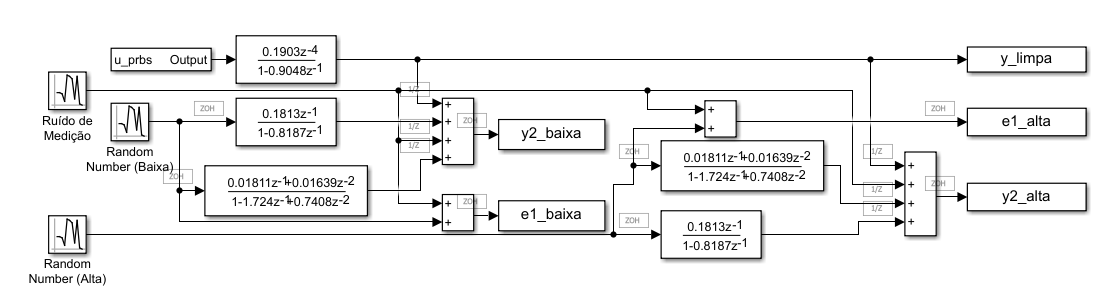

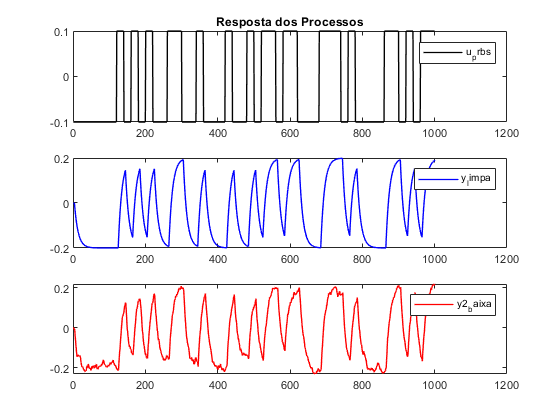

sim('Lista_3_ex_b');
grid;
hold on;   
t = tiledlayout(3,1);
ax1 = nexttile;
plot(i_prbs,'black','linewidth',1);
legend('u_prbs'); title({'Resposta dos Processos'});
ax2 = nexttile;
plot(y_limpa,'blue','linewidth',1);   
legend('y_limpa');
ax3 = nexttile;
plot(y2_baixa,'red','linewidth',1);  
legend('y2_baixa');

linkaxes([ax1,ax2,ax3],'x');

**C.** Realize uma validação cruzada via comando “compare” (com y limpo e y2 com perturbações de alta e baixa intensidade), de todos os modelos obtidos no item “g” da 2ª lista de  exercícios, gerados através de excitação degrau, ao se aplicar em u o sinal PRBS lento  criado no item “a”. 

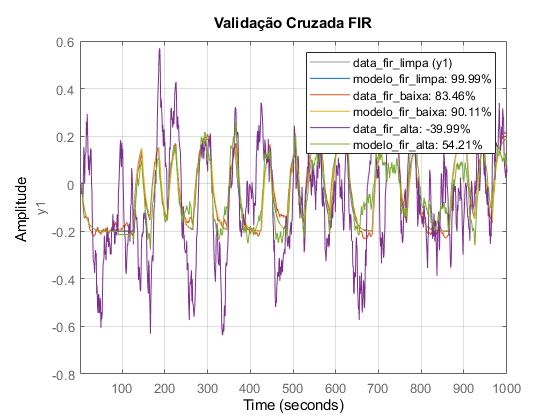

clc; clear; close all; warning off;

i_prbs = idinput(1001,'prbs',[0 (1/20)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);

sim('Lista_3_ex_c');

% FIR
data_fir_limpa = iddata(y_limpa,i_prbs);
modelo_fir_limpa = arx(data_fir_limpa,[0 88 3]);

data_fir_baixa = iddata(y2_baixa,i_prbs);
modelo_fir_baixa = arx(data_fir_baixa,[0 88 3]);

data_fir_alta = iddata(y2_alta,i_prbs);
modelo_fir_alta = arx(data_fir_alta,[0 88 3]);

compare(data_fir_limpa,modelo_fir_limpa,data_fir_baixa, ...
    modelo_fir_baixa,data_fir_alta,modelo_fir_alta);  
grid; title({'Validação Cruzada FIR'});

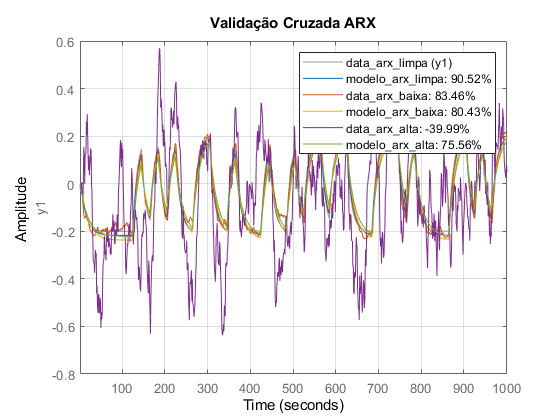



% ARX
data_arx_limpa = iddata(y_limpa,i_prbs);
modelo_arx_limpa = arx(data_arx_limpa,[1 2 3]);

data_arx_baixa = iddata(y2_baixa,i_prbs);
modelo_arx_baixa = arx(data_arx_baixa,[1 2 3]);

data_arx_alta = iddata(y2_alta,i_prbs);
modelo_arx_alta = arx(data_arx_alta,[1 2 3]);

compare(data_arx_limpa,modelo_arx_limpa,data_arx_baixa, ...
    modelo_arx_baixa,data_arx_alta,modelo_arx_alta);
grid; title({'Validação Cruzada ARX'});

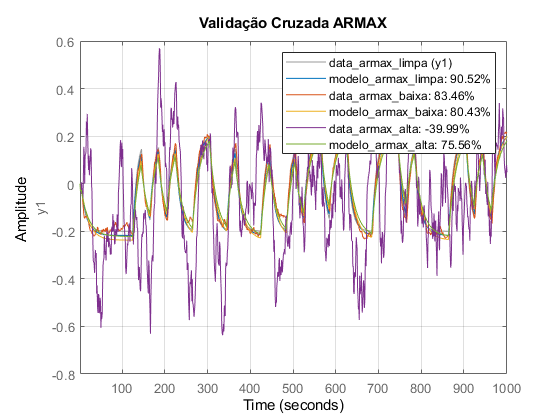


% ARMAX
data_armax_limpa = iddata(y_limpa,i_prbs);
modelo_armax_limpa = armax(data_armax_limpa,[1 2 0 3]);

data_armax_baixa = iddata(y2_baixa,i_prbs);
modelo_armax_baixa = armax(data_armax_baixa,[1 2 0 3]);

data_armax_alta = iddata(y2_alta,i_prbs);
modelo_armax_alta = armax(data_armax_alta,[1 2 0 3]);

compare(data_armax_limpa,modelo_armax_limpa,data_armax_baixa, ...
    modelo_armax_baixa,data_armax_alta,modelo_armax_alta);
grid; title({'Validação Cruzada ARMAX'});

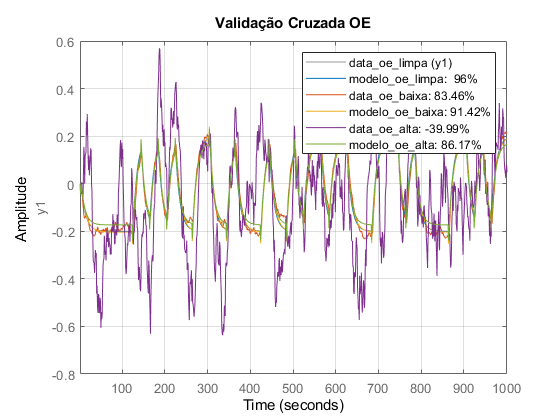


% OE
data_oe_limpa = iddata(y_limpa,i_prbs);
modelo_oe_limpa = oe(data_oe_limpa,[2 1 3]);

data_oe_baixa = iddata(y2_baixa,i_prbs);
modelo_oe_baixa = oe(data_oe_baixa,[2 1 3]);

data_oe_alta = iddata(y2_alta,i_prbs);
modelo_oe_alta = oe(data_oe_alta,[2 1 3]);

compare(data_oe_limpa,modelo_oe_limpa,data_oe_baixa, ...
    modelo_oe_baixa,data_oe_alta,modelo_oe_alta);
grid; title({'Validação Cruzada OE'});

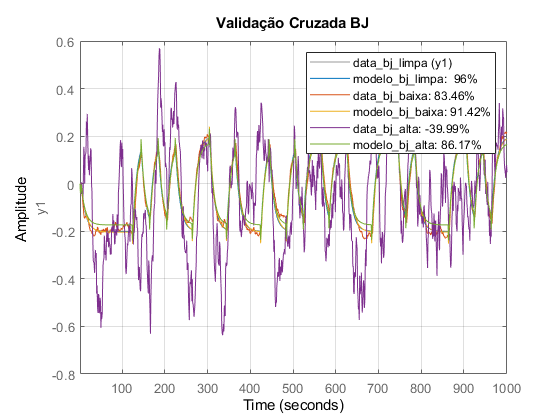


% BJ
data_bj_limpa = iddata(y_limpa,i_prbs);
modelo_bj_limpa = bj(data_bj_limpa,[2 0 0 1 3]);

data_bj_baixa = iddata(y2_baixa,i_prbs);
modelo_bj_baixa = bj(data_bj_baixa,[2 0 0 1 3]);

data_bj_alta = iddata(y2_alta,i_prbs);
modelo_bj_alta = bj(data_bj_alta,[2 0 0 1 3]);

compare(data_bj_limpa,modelo_bj_limpa,data_bj_baixa, ...
    modelo_bj_baixa,data_bj_alta,modelo_bj_alta);
grid; title({'Validação Cruzada BJ'});

**D.** Repita o item anterior, mas utilizando o sinal PRBS rápido gerado no item “a’. O resultado  da validação cruzada do item anterior melhora ou piora? Por que? 

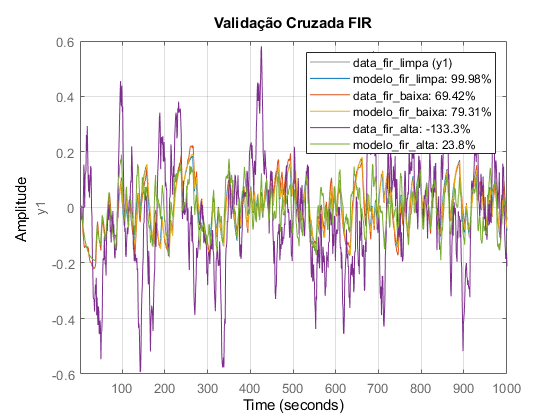

clc; clear; close all; warning off;

i_prbs = idinput(1001,'prbs',[0 (1/4)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);

sim('Lista_3_ex_c');

% FIR
data_fir_limpa = iddata(y_limpa,i_prbs);
modelo_fir_limpa = arx(data_fir_limpa,[0 88 3]);

data_fir_baixa = iddata(y2_baixa,i_prbs);
modelo_fir_baixa = arx(data_fir_baixa,[0 88 3]);

data_fir_alta = iddata(y2_alta,i_prbs);
modelo_fir_alta = arx(data_fir_alta,[0 88 3]);

compare(data_fir_limpa,modelo_fir_limpa,data_fir_baixa, ...
    modelo_fir_baixa,data_fir_alta,modelo_fir_alta);  
grid; title({'Validação Cruzada FIR'});

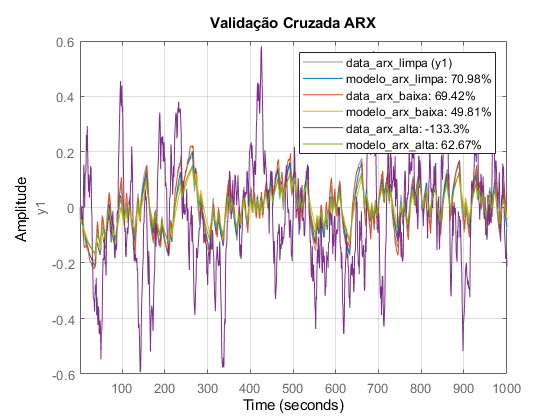



% ARX
data_arx_limpa = iddata(y_limpa,i_prbs);
modelo_arx_limpa = arx(data_arx_limpa,[1 2 3]);

data_arx_baixa = iddata(y2_baixa,i_prbs);
modelo_arx_baixa = arx(data_arx_baixa,[1 2 3]);

data_arx_alta = iddata(y2_alta,i_prbs);
modelo_arx_alta = arx(data_arx_alta,[1 2 3]);

compare(data_arx_limpa,modelo_arx_limpa,data_arx_baixa, ...
    modelo_arx_baixa,data_arx_alta,modelo_arx_alta);
grid; title({'Validação Cruzada ARX'});

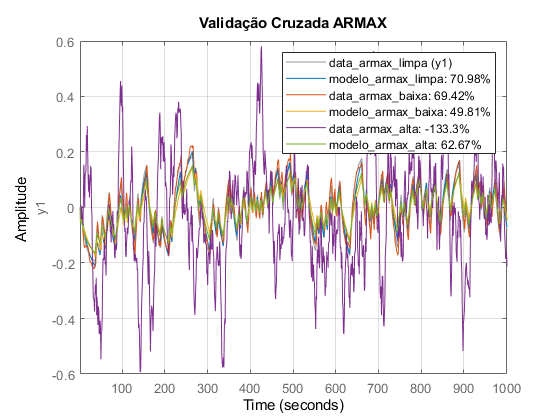


% ARMAX
data_armax_limpa = iddata(y_limpa,i_prbs);
modelo_armax_limpa = armax(data_armax_limpa,[1 2 0 3]);

data_armax_baixa = iddata(y2_baixa,i_prbs);
modelo_armax_baixa = armax(data_armax_baixa,[1 2 0 3]);

data_armax_alta = iddata(y2_alta,i_prbs);
modelo_armax_alta = armax(data_armax_alta,[1 2 0 3]);

compare(data_armax_limpa,modelo_armax_limpa,data_armax_baixa, ...
    modelo_armax_baixa,data_armax_alta,modelo_armax_alta);
grid; title({'Validação Cruzada ARMAX'});

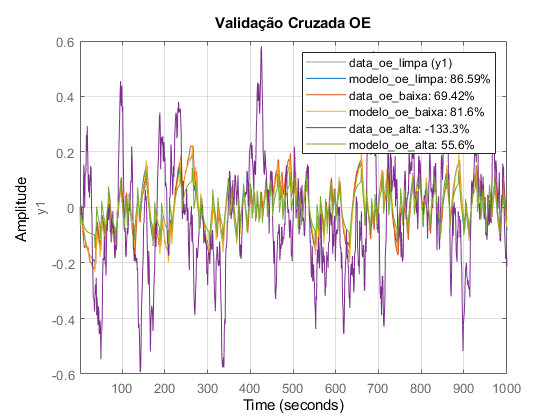


% OE
data_oe_limpa = iddata(y_limpa,i_prbs);
modelo_oe_limpa = oe(data_oe_limpa,[2 1 3]);

data_oe_baixa = iddata(y2_baixa,i_prbs);
modelo_oe_baixa = oe(data_oe_baixa,[2 1 3]);

data_oe_alta = iddata(y2_alta,i_prbs);
modelo_oe_alta = oe(data_oe_alta,[2 1 3]);

compare(data_oe_limpa,modelo_oe_limpa,data_oe_baixa, ...
    modelo_oe_baixa,data_oe_alta,modelo_oe_alta);
grid; title({'Validação Cruzada OE'});

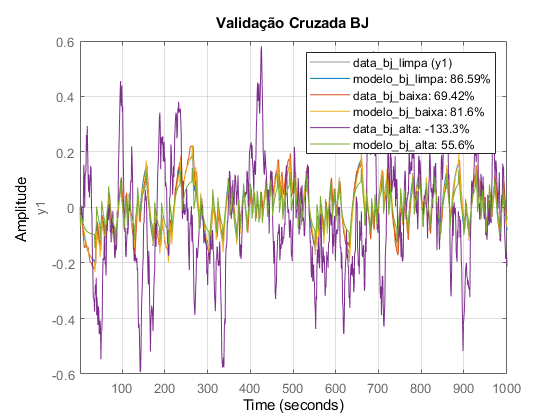


% BJ
data_bj_limpa = iddata(y_limpa,i_prbs);
modelo_bj_limpa = bj(data_bj_limpa,[2 0 0 1 3]);

data_bj_baixa = iddata(y2_baixa,i_prbs);
modelo_bj_baixa = bj(data_bj_baixa,[2 0 0 1 3]);

data_bj_alta = iddata(y2_alta,i_prbs);
modelo_bj_alta = bj(data_bj_alta,[2 0 0 1 3]);

compare(data_bj_limpa,modelo_bj_limpa,data_bj_baixa, ...
    modelo_bj_baixa,data_bj_alta,modelo_bj_alta);
grid; title({'Validação Cruzada BJ'});

podemos perceber que ao mudar Tb = 4*T, houve significativa queda nos fits, ou seja, o resultado da validação cruzada piorou. Isto ocorre porque  Tb = 20*T, o tempo disponível para acomodação era maior.

**E. **Excite o processo com um sinal do tipo PRBS lento gerado no item “a”. Aplique esse sinal  no processo afetado por perturbações de baixa e alta intensidade e ruído de medição,  considerando as sementes originalmente empregadas para gerá-las (sementes usadas na  2ª lista de exercícios). Identifique e apresente modelos com estrutura FIR, ARX, ARMAX,  OE e BJ utilizando os 601 primeiros pontos coletados. 

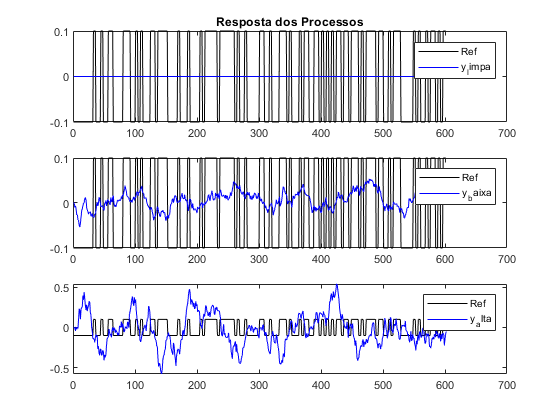

clc;clear;close all;warning off;
i_prbs = idinput(601,'prbs',[0 (1/4)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);
Sim_Timer = 601;
sim('Lista_3_ex_e');
grid;
hold on;   
t = tiledlayout(3,1);
ax1 = nexttile;
plot(i_prbs,'black'); hold on; plot(y_limpa,'b');
legend('Ref','y_limpa'); title({'Resposta dos Processos'});

ax2 = nexttile;
plot(i_prbs,'black'); hold on; plot(y2_baixa,'b');   
legend('Ref','y_baixa');

ax3 = nexttile;
plot(i_prbs,'black'); hold on; plot(y2_alta,'b');  
legend('Ref','y_alta');

linkaxes([ax1,ax2,ax3],'x');

**F.** Use os 400 pontos finais coletados no item anterior para realizar uma validação cruzada  dos modelos obtidos no item anterior. Analise a qualidade dos modelos obtidos via  comando “compare”. Apresente em uma tabela o valor dos índices fit obtidos para cada  modelo e para os casos de perturbação de baixa e alta intensidade.

clc;clear;close all;warning off;
i_prbs = idinput(600,'prbs',[0 (1/4)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);
Sim_Timer = 600;
sim('Lista_3_ex_e');

%Separa a entrada em 400
u_prbs_400=zeros(600,1);
for i=200:600
u_prbs_400(i)=i_prbs(i);
end;


%Separa a saida em 400
y2_baixa_400=zeros(600,1);
for i=200:600
y2_baixa_400(i)=y2_baixa(i);
end;

% data_601 = iddata(y2_baixa_601,u_prbs_601);

data_400 = iddata(y2_baixa_400,u_prbs_400);

%FIR
 modelo_fir_400 = arx(data_400,[0 88 3]);
%ARX
 modelo_arx_400 = arx(data_400,[1 2 3]);
%ARMAX
 modelo_armax_400 = armax(data_400,[1 2 0 3]);
%OE
 modelo_oe_400 = oe(data_400,[2 1 3]);
%BJ
 modelo_bj_400 = bj(data_400,[2 0 0 1 3]);

Comparando os modelos gerados:

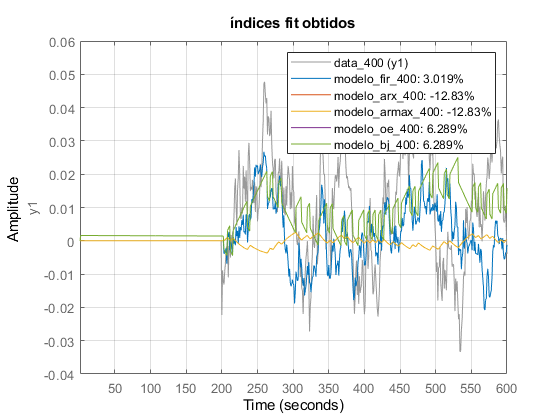

compare(data_400,modelo_fir_400,modelo_arx_400,modelo_armax_400,modelo_oe_400,modelo_bj_400);
grid; title({'índices fit obtidos'});

**G.** Realize uma validação cruzada de todos os modelos obtidos no item “e” com sinal PRBS  lento, empregando como sinal de entrada um degrau unitário de amplitude 0,1 aplicado em  t=275 s. Simule a planta por 600 s. Ao aplicar o comando “compare”, como ficou a resposta  dos modelos ao degrau? Apresente em uma tabela o valor dos índices fit obtidos para cada  modelo e para os casos de perturbação de baixa e alta intensidade.

clc;clear;close all;warning off;
i_prbs = idinput(600,'prbs',[0 (1/4)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);
Sim_Timer = 600;
sim('Lista_3_ex_e');

%Separa a entrada em 600
u_prbs_600=zeros(600,1);
for i=1:600
u_prbs_600(i)=i_prbs(i);
end;


%Separa a saida em 600
y2_baixa_600=zeros(600,1);
for i=1:600
y2_baixa_600(i)=y2_baixa(i);
end;

data_600 = iddata(y2_baixa_600,u_prbs_600);

%FIR
 modelo_fir_600 = arx(data_600,[0 88 3]);
%ARX
 modelo_arx_600 = arx(data_600,[1 2 3]);
%ARMAX
 modelo_armax_600 = armax(data_600,[1 2 0 3]);
%OE
 modelo_oe_600 = oe(data_600,[2 1 3]);
%BJ
 modelo_bj_600 = bj(data_600,[2 0 0 1 3]);

Comparando os modelos gerados:

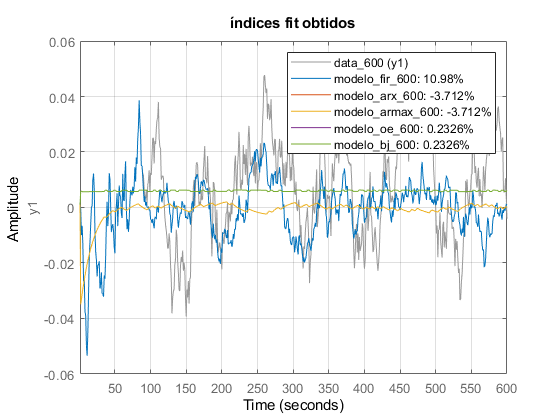

compare(data_600,modelo_fir_600,modelo_arx_600,modelo_armax_600,modelo_oe_600,modelo_bj_600);
grid; title({'índices fit obtidos'});

**H.** Calcule e apresente em uma tabela o ganho estacionário dos modelos obtidos com PRBS  lento. Compare esses valores com o ganho estacionário do processo real. Comente os  resultados obtidos. Que estrutura de modelo gerou o melhor ganho estacionário do  processo nos casos de baixa e de alta perturbação? 

Em comparação com o ganho estacionário do processo, foi consideravelmente baixo, uma vez que os fits stão por volta dos 80%, com excessão dos modelos ARX e ARMAX, que estão com fits por volta de 50%.

**I.** Repita a validação cruzada com entrada degrau citada no item “g”, mas gerando os  modelos com um sinal PRBS rápido. Ao aplicar o comando “compare”, como ficou a  resposta dos modelos ao degrau? Apresente em uma tabela o valor dos índices fit obtidos  para cada modelo e para os casos de perturbação de baixa e alta intensidade. Comparando  esta validação com aquela feita com os modelos gerados pelo sinal PRBS lento, qual gerou  melhores resultados? Por que? 

clc;clear;close all;warning off;
i_prbs = idinput(600,'prbs',[0 (1/20)],[-0.1 0.1]);
u_prbs = iddata(i_prbs);
Sim_Timer = 600;
sim('Lista_3_ex_e');

%Separa a entrada em 600
u_prbs_600=zeros(600,1);
for i=1:600
u_prbs_600(i)=i_prbs(i);
end;


%Separa a saida em 600
y2_baixa_600=zeros(600,1);
for i=1:600
y2_baixa_600(i)=y2_baixa(i);
end;

data_600 = iddata(y2_baixa_600,u_prbs_600);

%FIR
 modelo_fir_600 = arx(data_600,[0 88 3]);
%ARX
 modelo_arx_600 = arx(data_600,[1 2 3]);
%ARMAX
 modelo_armax_600 = armax(data_600,[1 2 0 3]);
%OE
 modelo_oe_600 = oe(data_600,[2 1 3]);
%BJ
 modelo_bj_600 = bj(data_600,[2 0 0 1 3]);

Comparando os modelos gerados:

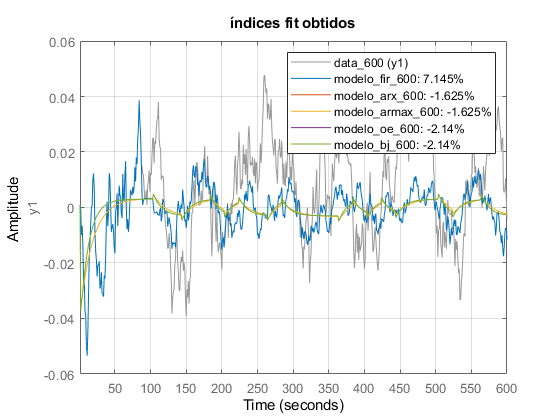

compare(data_600,modelo_fir_600,modelo_arx_600,modelo_armax_600,modelo_oe_600,modelo_bj_600);
grid; title({'índices fit obtidos'});

**J.** Calcule e apresente em uma tabela o ganho estacionário dos modelos obtidos com PRBS  rápido junto aos ganhos obtidos no item “h”. Compare esses valores com o ganho  estacionário do processo real. Que estrutura de modelo gerou o melhor ganho estacionário  do processo nos casos de baixa e de alta perturbação? Os melhores resultados foram  obtidos usando o sinal PRBS rápido ou lento? Justifique a sua resposta.

Em comparação com o ganho estacionário do processo, foi consideravelmente baixo, uma vez que os fits stão por volta dos 93%, com excessão dos modelos ARX e ARMAX, que estão com fits por volta de 101%.

Se comparado ao PRBS lento, todos os modelos gerados com PRBS rápido estão com fit menor que os modelos gerados com PRBS lento.